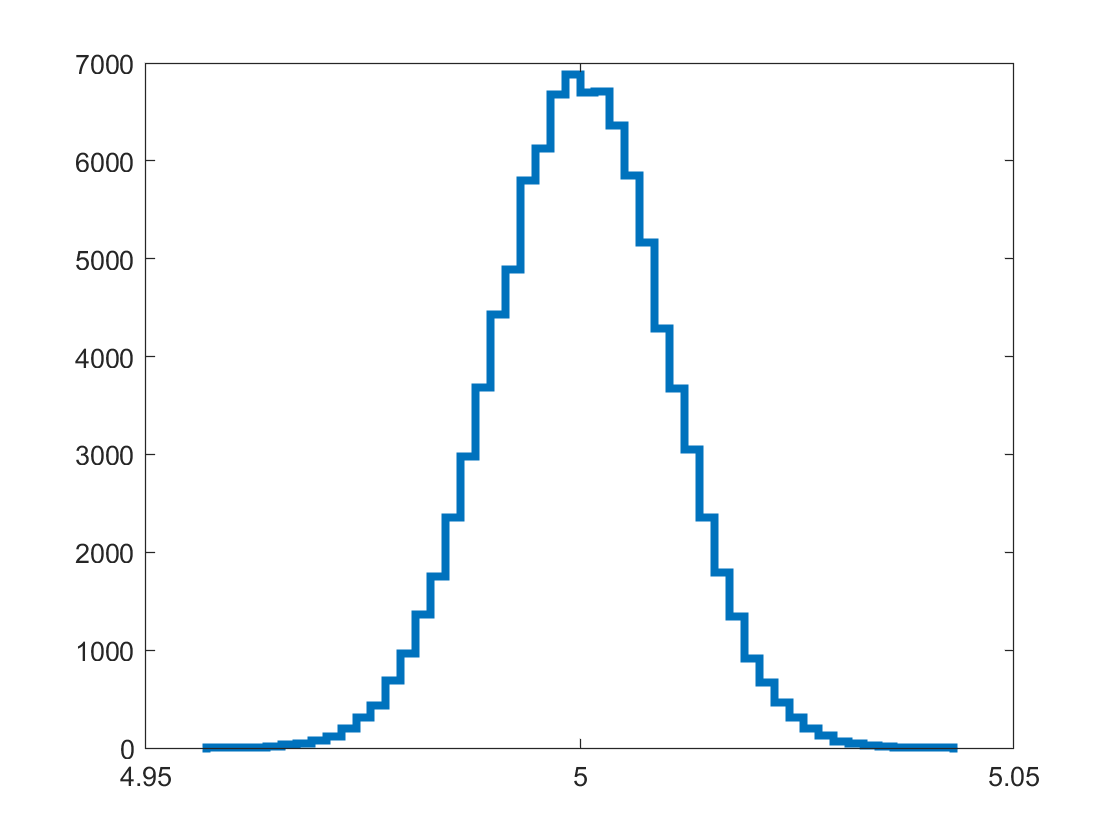

d = random('Normal', 5., 0.01, [1,100000]);
% d is the data set, randomly generated according to a normal distribution
% 5 is the centerof the distribution
histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3)
xlim([4.95,5.05])

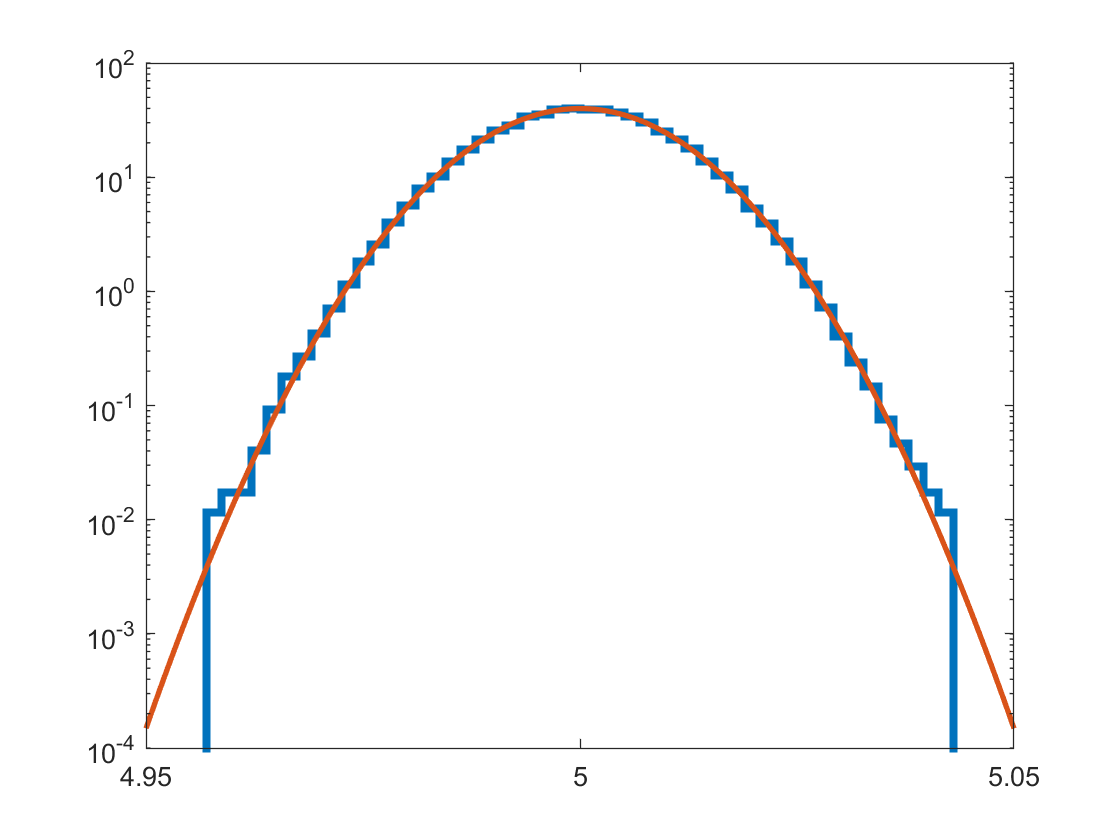

% xlim pretty self-explanatory 

histogram(d,50,'DisplayStyle',"stairs",'Linewidth',3,"Normalization","pdf")
% maybe takes the histogram from above and normalizes it? Still not sure
% about pdf... 
hold on
% hold on refers to the data, so that the following code affects the
% histogram I've already made, I think... OH!! It makes it so that the
% histrogram is overlayed with the curve that I'm making below!! Same axes!
x = linspace(4.95,5.05,1000);
% x is a vector containing the points from 4.95 to 5.05 st there are 1000
% numbers in the vector
pd = makedist("Normal","mu",5.,"sigma",0.01);
% mu is mean; sigma is the standard deviation
plot(x,pdf(pd,x),"Linewidth",2);
% plotting x versus pdf(pd,x)... pdf??
set(gca, 'YScale','log')

% makes y axis log scale -- important!!